# Exam June 2018

## Problem 1: Wiener filter

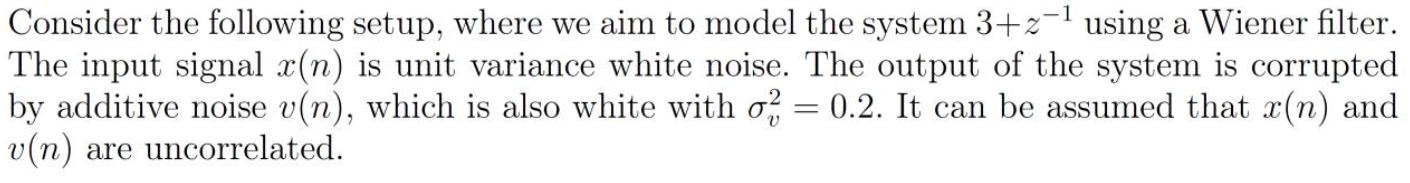

        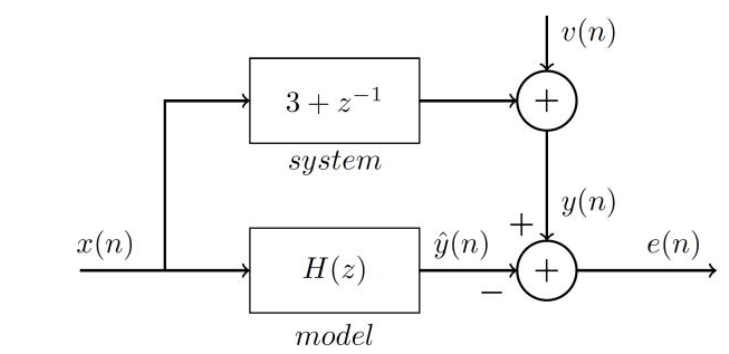

$x\left(n\right)~\mathrm{WN}\left(0,1\right)$ ,$v\left(n\right)~\mathrm{WN}\left(0,0\ldotp 2\right)$and $x\left(n\right)$ and $v\left(n\right)$ are uncorrelated

clear variables;


### [✔] 1) Calcuate the autocorrelation matrix and cross-correction vector

Since $x\left(n\right)~\textrm{WN}\left(0,1\right)$, its autocorrelation function is:

        
$$r_{\mathrm{xx}} \left(\ell \right)=\sigma_x^2 \delta \left(\ell \right)=\delta \left(\ell \right)$$


The autocorrelation matrix ${\mathbf{R}}_x$ is therefore

M = 2;
ell = 0:M-1;
r_xx = [1, 0];
R_xx = toeplitz(r_xx)

From the drawing, we know that the output of the system is:

        
$$y\left(n\right)=3x\left(n\right)+x\left(n-1\right)+v\left(n\right)$$


Now, we can compute the cross-correlation vector $g$:

        
$$r_{\mathrm{xy}} \left(\ell \right)=E\left\lbrack x\left(n\right)y\left(n-\ell \right)\right\rbrack$$


                  
$$=E\left\lbrack x\left(n\right)\left(3x\left(n-\ell \right)+x\left(n-\ell -1\right)+v\left(n-\ell \right)\right)\right\rbrack$$


                  
$$=E\left\lbrack 3x\left(n\right)x\left(n-\ell \right)+x\left(n\right)x\left(n-\ell -1\right)+x\left(n\right)v\left(n-\ell \right)\right\rbrack$$


                  
$$=3E\left\lbrack x\left(n\right)x\left(n-\ell \right)\right\rbrack +E\left\lbrack x\left(n\right)x\left(n-\ell -1\right)\right\rbrack +E\left\lbrack x\left(n\right)v\left(n-\ell \right)\right\rbrack$$


                  
$$=3r_{\mathrm{xx}} \left(\ell \right)+r_{\mathrm{xx}} \left(\ell -1\right)+E\left\lbrack x\left(n\right)v\left(n-\ell \right)\right\rbrack$$


If we assume that $x\left(n\right)$ and $v\left(n\right)$ are uncorrelated then:

                  
$$=3r_{\textrm{xx}} \left(\ell \right)+r_{\textrm{xx}} \left(\ell -1\right)$$


Since $r_{\textrm{xx}} \left(\ell \right)=\delta \left(\ell \right)$ then: 

        
$$r_{\mathrm{xy}} \left(\ell \right)=3\delta \left(\ell \right)+\delta \left(\ell -1\right)$$


Thus, the cross-correlation vector $g$ is:

        
$$\mathit{\mathbf{g}}=\left\lbrack \begin{array}{c}
3\\
1
\end{array}\right\rbrack$$


### [✔] 2) Calculate the expected energy

From the drawing, we know that the output of the system is:

        
$$y\left(n\right)=3x\left(n\right)+x\left(n-1\right)+v\left(n\right)$$


Let us first expand $y^2 \left(n\right)$:

syms n x(n) v(n)
expand((3*x(n) + x(n-1) + v(n))^2)

ans =     6.0855   -2.7605   -2.6160    4.1680   -1.0665


Now, compute the expectation of each term:

        
$$E\left\lbrack x^2 \left(n-1\right)\right\rbrack =E\left\lbrack x\left(n\right)x\left(n\right)\right\rbrack =r_{\mathrm{xx}} \left(0\right)=1\cdot \delta \left(0\right)=1\cdot 1=1$$


        $E\left\lbrack 2x\left(n-1\right)v\left(n\right)\right\rbrack =2E\left\lbrack x\left(n-1\right)v\left(n\right)\right\rbrack =0$ (because $x\left(n\right)$ and $v\left(n\right)$ are uncorrelated)

        
$$E\left\lbrack 6x\left(n-1\right)x\left(n\right)\right\rbrack =6r_{\mathrm{xx}} \left(1\right)=6\delta \left(1\right)=6\cdot 0=0$$


        
$$E\left\lbrack v^2 \left(n\right)\right\rbrack =r_{\mathrm{vv}} \left(0\right)=0\ldotp 2\cdot \delta \left(0\right)=0\ldotp 2\cdot 1=0\ldotp 2$$


        $E\left\lbrack 6v\left(n\right)x\left(n\right)\right\rbrack =6r_{\mathrm{xv}} \left(0\right)=6\cdot 0=0$ (because $x\left(n\right)$ and $v\left(n\right)$ are uncorrelated)

        
$$E\left\lbrack 9x\left(n\right)x\left(n\right)\right\rbrack =9r_{\mathrm{xx}} \left(0\right)=9\delta \left(0\right)=9\cdot 1=9$$


The expected energy is:

        
$$E\left\lbrack y^2 \left(n\right)\right\rbrack =1+0\ldotp 2+9=10\ldotp 2$$


### [✔] 3) Solve for H(z) and comment on the influence of v(n)

The second order Wiener filter for estimating the signal $y\left(n\right)$ is given by:

        
$$\hat{y} \left(n\right)=h_1 x\left(n\right)+h_2 x\left(n-1\right)$$


The optimum Wiener filter to estimate a random process is given by Eq. 14.109:

        

where ${\mathit{\mathbf{R}}}_x$ is the correlation matrix of a random vector $\mathit{\mathbf{x}}$ and $\mathit{\mathbf{g}}$ is the cross-correlation vector between $\mathit{\mathbf{x}}$ and $y$

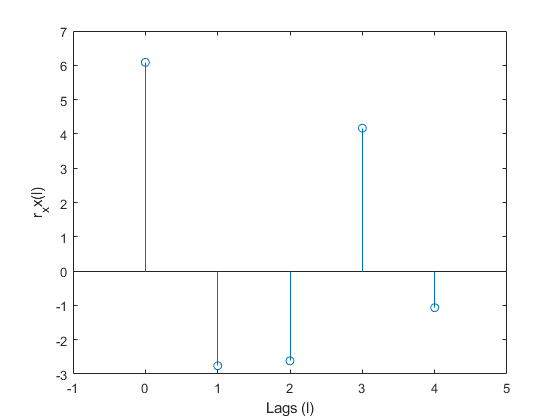

g = [3, 1]';
R_xx = [[1, 0]; 
        [0, 1]];
h_opt = R_xx\g

The optimal Wiener filter is:

        
$$H\left(z\right)=3+z^{-1}$$


This is exactly the system that we are trying to model.

## Problem 2: Signal Modelling

clear variables;

ans =     6.0855   -2.7605   -2.6160    4.1680   -1.0665


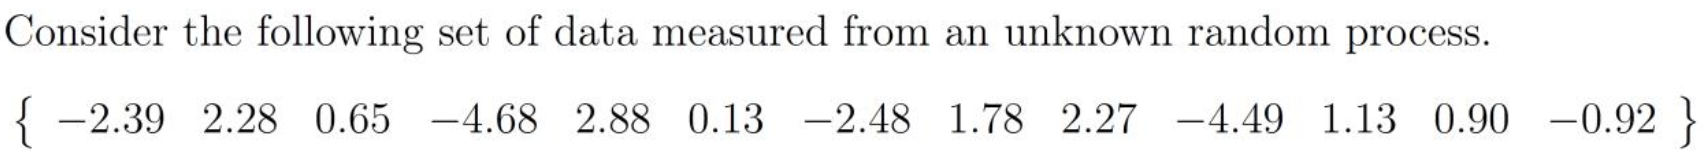

### [✔] 1) Calculate and plot the autocorrelation function of the data

x = [-2.39, 2.28, 0.65, -4.68, 2.88, 0.13, -2.48, 1.78, 2.27, -4.49, 1.13, 0.9, -0.92];

a =     0.8167
    0.8003


v = 1.7374

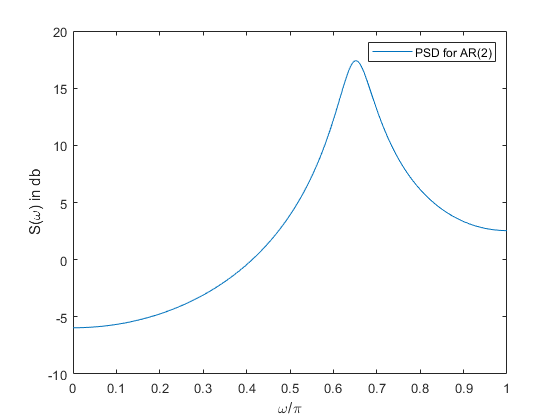


% Estimate autocorrelation using data
[r_xx, ell] = xcorr(x, 'biased');

% Print out the lags 0 to 4

mid = floor(numel(ell)/2)+1;
r_xx(mid:mid+4)
% Plot the results
stem(0:4, r_xx(mid:mid+4))
xlim([-1, 5])
xlabel('Lags (l)')
ylabel('r_xx(l)')

### [✔] 2) Can data be described by an MA(2) model?

MA(2) model is given by:

        
$$y\left\lbrack n\right\rbrack =b_0 \;x\left\lbrack n\right\rbrack +b_1 \;x\left\lbrack n-1\right\rbrack +b_2 \;x\left\lbrack n-2\right\rbrack$$


where $x\left\lbrack n\right\rbrack ~\mathrm{WN}\left(0,\sigma_x^2 \right)$ 

The autocorrelation for an MA(2) process is:

        
$$r_{\mathrm{yy}} \left(\ell \right)=\left(b_0^2 +b_1^2 +b_2^2 \right)\delta \left(\ell \right)+\left(b_0 b_1 +b_1 b_2 \right)\delta \left(\ell +1\right)+\left(b_0 b_1 +b_1 b_2 \right)\delta \left(\ell -1\right)+b_0 b_2 \delta \left(\ell +2\right)+b_0 b_2 \delta \left(\ell -2\right)$$


Clearly, the autocorrelation for an MA(2) for $\ell >2$ is zero.

The estimated autocorrelation for the data is:

r_xx(mid:mid+4)

Since the estimated autocorrelation has non-zero values for $\ell >2$, it cannot be described by an MA(2) model.

### [✔] 3) Calculate the power spectral density of the random process assuming an AR(2) model

Before we can compute the PSD, we need to find the AR(2) model coefficients.

An AR(p) model is given by:

        
$$y\left(n\right)=-\sum_{k=1}^p \left\lbrack a_k \;y\left(n-k\right)\right\rbrack +b_0 x\left(n\right)$$


The autocorrelation of AR(q) model was derived in Eq. 13.141 as:

        
$$r_{\mathrm{yy}} \left(\ell \right)=-\sum_{k=1}^p a_k r_{\mathrm{yy}} \left(\ell -k\right),\;\;\;\ell >0$$
 

This is useful because we can use it to find the coefficients $\left\lbrace a_k \right\rbrace$ of an AR(q) model using the autocorrelation $r_{\mathrm{yy}} \left(\ell \right)$ computed numerically in MATLAB. This means that the expression in Eq. 13.141 becomes a set of $p$ linear equations.

An AR(2) model is given by:

        
$$y\left(n\right)=-\left(a_1 \;y\left(n-1\right)+a_2 \;y\left(n-2\right)\right)+b_0 x\left(n\right)$$


We can estimate the model parameters of a second-order AR model$p=2$ by creating two equations with two unknowns:

        
$$r_{\mathrm{yy}} \left(1\right)=-a_1 r_{\mathrm{yy}} \left(0\right)-a_2 r_{\mathrm{yy}} \left(-1\right)$$


        
$$r_{\textrm{yy}} \left(2\right)=-a_1 r_{\textrm{yy}} \left(1\right)-a_2 r_{\textrm{yy}} \left(0\right)$$


We can write it into matrix form using the Toeplitz matrix:

        
$$\left\lbrack \begin{array}{cc}
r_{\mathrm{yy}} \left(0\right) & r_{\mathrm{yy}} \left(-1\right)\\
r_{\mathrm{yy}} \left(1\right) & r_{\mathrm{yy}} \left(0\right)
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
a_1 \\
a_2 
\end{array}\right\rbrack =-\left\lbrack \begin{array}{c}
r_{\mathrm{yy}} \left(1\right)\\
r_{\mathrm{yy}} \left(2\right)
\end{array}\right\rbrack$$


In the general case, it becomes:

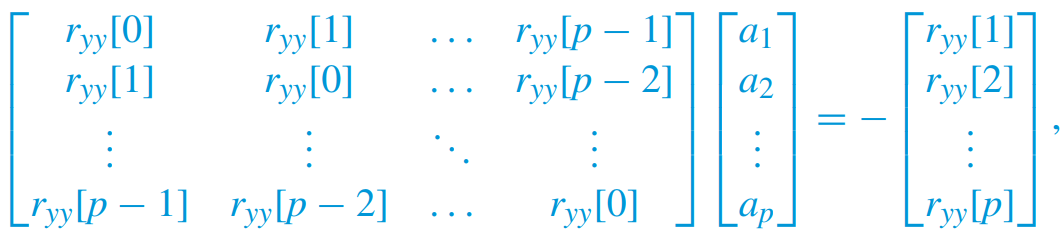

More compactly written as:

        
$${\mathit{\mathbf{R}}}_y \;\mathit{\mathbf{a}}=-{\mathit{\mathbf{r}}}_y$$


This is a system of linear equations which can be solved in MATLAB using `arfit` function (see bottom of the document).

The power spectrum of an ARMA(p, q) process is given by:

        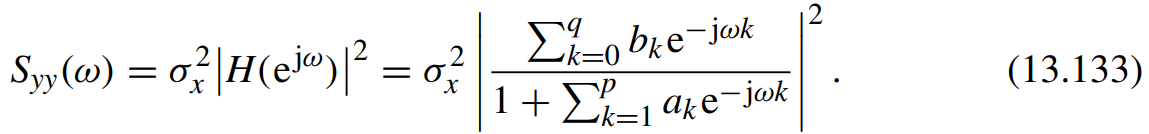

The power spectrum of an AR(p) process is given by:

        
$$S_{\mathrm{yy}} \left(\omega \right)=\sigma_x^2 {\left|\frac{1}{1+\sum_{k=1}^p a_k e^{-j\omega k} }\right|}^2$$


To solve this problem, the method is as follows:

- Find the coefficents $\left\lbrace a_1 ,a_2 ,\cdots ,a_p \right\rbrace$ for the$\mathrm{AR}\left(p\right)$ model

- Compute the transfer function for the $\mathrm{AR}\left(p\right)$ by computing the sum and finding its reciprocal

- Compute the conjugate of the transfer function: ${\left|H\left(e^{j\omega } \right)\right|}^2$

- Multiply it with the variance $\sigma_x^2$

The method above is implemented in the functions `arfit()` and `ar2psd():`

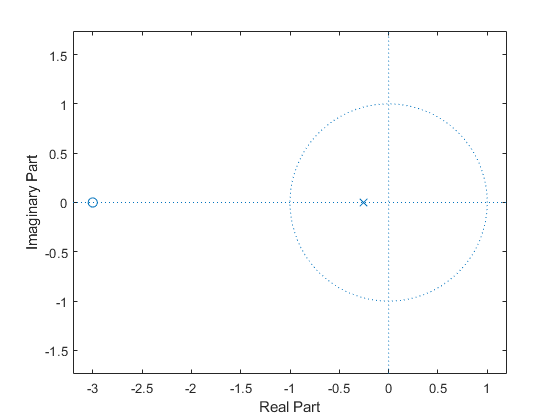

[a, v] = arfit(x, 2)
[S, w] = ar2psd(a, v, 256);

plot(w/pi, real(pow2db(S)))
legend('PSD for AR(2)')
xlabel('\omega/\pi')
ylabel('S(\omega) in db')

## Problem 3: True/False Questions

clear variables;

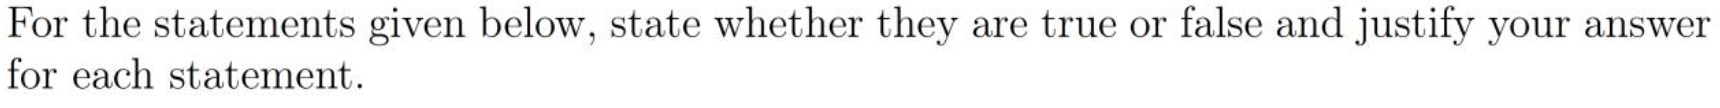

### [✔] 1) When is a system invertible?

Answer: FALSE!

A filter $H\left(z\right)=\frac{B\left(z\right)}{A\left(z\right)}$ is said to be stable and causal if all the poles of $H\left(z\right)$ are inside the unit circle.

If the inverse filter $H_{\mathrm{inv}} \left(z\right)=\frac{A\left(z\right)}{B\left(z\right)}$ has to be stable and causal, then all the poles of $H_{\textrm{inv}} \left(z\right)$ must be inside the unit circle or equivalently all zeros of $H\left(z\right)$ must be inside the unit circle.

In practice, we say that a system is invertible if its zeros and poles are inside the unit circle (minimum phase).

Plotting the poles and zeros of the given system function, we observe that the zero is outside the unit circle.

b = [1, 3];
a = [1, 1/4];
zplane(b, a)

### [✔] 2) The Hilbert transform of a triangular wave signal is another triangular wave signal

Answer: FALSE.

The Hilbert transform rotates the Fourier coefficients in the complex space which converts the real components into the imaginary component. The quarter-cycle shifted signal is then added to the original signal. In other words, a Hilbert transform takes each frequency component present in the original signal and shifts its phase by $-\frac{\pi }{2}$.

The Hilbert transform of $\mathrm{cos}\left(\theta \right)$ is $\mathrm{sin}\left(\theta \right)$ i.e., a quarter-cycle shift.

        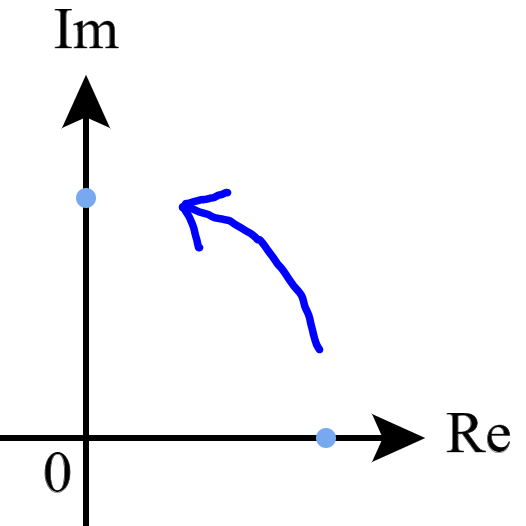

A triangular wave signal can thought of being composed of multiple frequency component. If each of these are shifted by 90 degrees then result is not a triangular wave signal.

We can experiment with it.

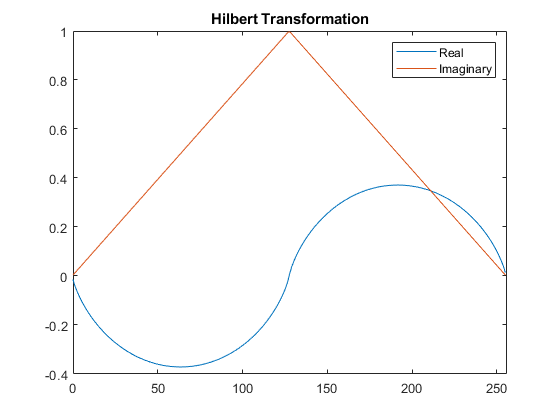

N = 256;
n = 0:N-1;
xr = triang(256);
x = hilbert(xr);

plot(n, imag(x), n, real(x))
legend('Real','Imaginary')
title('Hilbert Transformation')
xlim([0, N])

### [✔] 3) Leakage can be reduced in estimates of Power Spectral Density by applying a window function to the data.

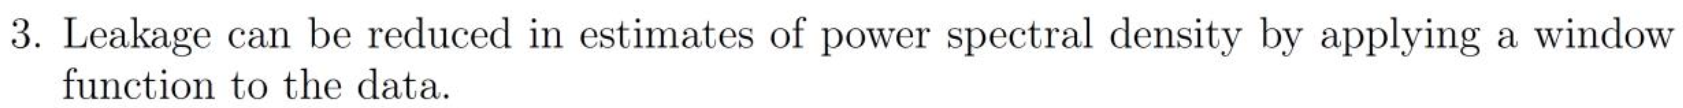

Answer: TRUE.

Leakage is an artefact of an FFT applied to a non-periodic data. Even if a signal is periodic like a sinousoid, when the signal is measured with some interval it can be non-periodic. The issue is that FFT  assumes that the signal is periodic and repeats itself after the measured interval. This is not the case when the data is non-periodic, which contains sharp transitions at the end of each measured interval. These sharp changes have a broad frequency response which lead to spectral leakage. Windows can help *minimize* the effects of leakage by smoothing the time domain signal, but cannot eliminate leakage.

## Problem 4: LMS algorithm

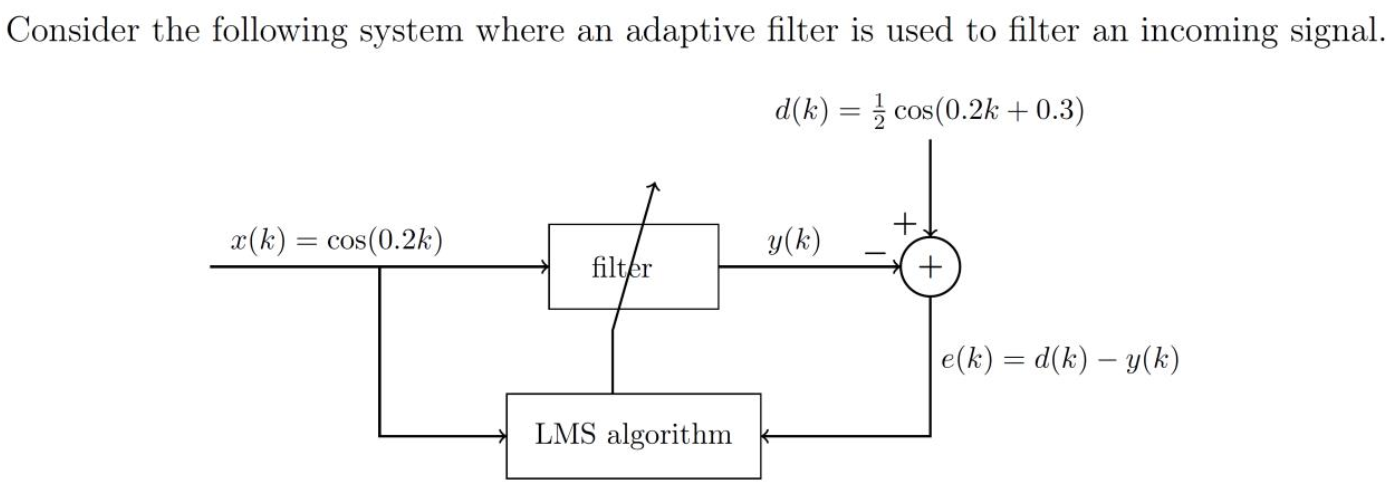

### 1) Compute the coefficients for the first three iterations of the algorithm

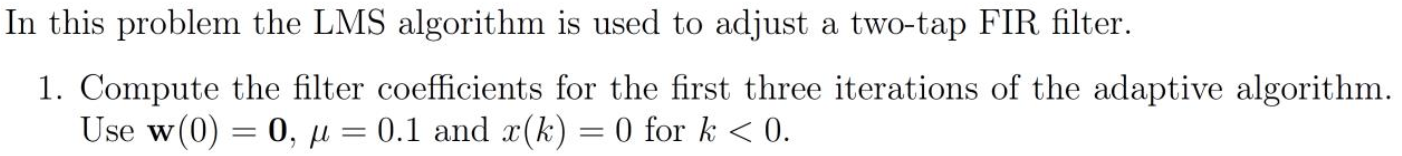

### 2) Discuss the pros and cons of increasing the step size

## Problem 5: Probability Density Functions

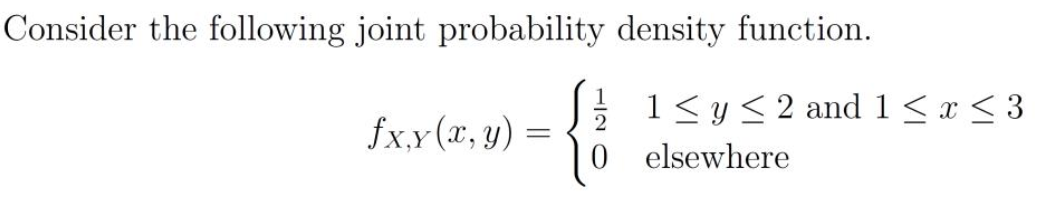

### [✔] 1) Show that the probability density function is valid

Integrate using MATLAB:

syms x y f(x,y) fX(x) fY(y)
f(x,y) = 1/2;
inner = int(f(x,y), x, 1, 3);
outer = int(inner, y, 1, 2)

$$outer = 1$$

% Alternative method is to numerically evaluate double integral
fun = @(x,y) 1/2 + 0*(x+y); % Hack: 0*(x+y) is added for MATLAB
integral2(fun, 1, 3, 1, 2)

ans = 1

### [✔] 2) Calculate the marginal probabiltiy density function

The marginal probability density function is given as:

            

The marginal probability for $X$ is given as:

        
$$f_X \left(x\right)=\int_1^2 \frac{1}{2}\;\textrm{dy}={\left\lbrack \frac{1}{2}y\right\rbrack }_1^2 =1-\frac{1}{2}=\frac{1}{2}$$


Check it in MATLAB:

fX(x) = int(f(x,y), y, 1, 2)

$$fX(x) = \frac{1}{2}$$

% Alternative method
fun = @(y) 1/2 + 0*y; % Hack!
integral(fun, 1, 2)

ans = 0.5000

The marginal probability for $Y$ is given as:

        
$$f_Y \left(y\right)=\int_1^3 \frac{1}{2}\;\textrm{dx}={\left\lbrack \frac{1}{2}x\right\rbrack }_1^3 =\frac{3}{2}-\frac{1}{2}=1$$


fY(y) = int(f(x,y), x, 1, 3)

$$fY(y) = 1$$

% Alternative method
fun = @(x) 1/2 + 0*x; % Hack!
integral(fun, 1, 3)

ans = 1.0000

### [✔] 3) Without calculations, argue whether var(X) or var(Y) is larger

The variance is a measure of the spread of the distribution about its mean value. A large variance indicates that the values of the random variable are spread over a wider interval about the mean. In this problem, $X$ has a wider span of possible values. Therefore, $\mathrm{var}\left(X\right)>\mathrm{var}\left(Y\right)$.

### [✔] 4) Show that X and Y are uncorrelated

Two random variables are uncorrelated if 

        $\mathrm{cov}\left(X,Y\right)=E\left(\mathrm{XY}\right)-E\left\lbrack X\right\rbrack E\left\lbrack Y\right\rbrack =0$   or   $E\left\lbrack \mathrm{XY}\right\rbrack =E\left\lbrack X\right\rbrack E\left\lbrack Y\right\rbrack$

The simplest way to show that $X$ and $Y$ are uncorrelated is if the two random variables are independent.

Two random variables $X$ and $Y$ are said to be independent if:

        
$$f_{X,Y} \left(x,y\right)=f_X \left(x\right)f_Y \left(y\right)$$


The joint probability is given as:

        
$$f_{X,Y} \left(x,y\right)=\frac{1}{2}$$


The marginal probability for $X$ is given as:

        
$$f_X \left(x\right)=\int_1^2 \frac{1}{2}\;\textrm{dy}={\left\lbrack \frac{1}{2}y\right\rbrack }_1^2 =1-\frac{1}{2}=\frac{1}{2}$$


The marginal probability for $Y$ is given as:

        
$$f_Y \left(y\right)=\int_1^3 \frac{1}{2}\;\textrm{dx}={\left\lbrack \frac{1}{2}x\right\rbrack }_1^3 =\frac{3}{2}-\frac{1}{2}=1$$


Since they are the random variables $X$ and $Y$ are indepedent they are also uncorrelated.

Another approach involves computing the covariance and showing that 

        
$$\mathrm{cov}\left(X,Y\right)=E\left(\mathrm{XY}\right)-E\left\lbrack X\right\rbrack E\left\lbrack Y\right\rbrack =0$$


We compute $E\left\lbrack X\right\rbrack$

        
$$E\left\lbrack X\right\rbrack =\int_{-\infty }^{\infty } x\;f_X \left(x\right)\;\mathrm{dx}=\int_1^3 \frac{1}{2}x\;\;\mathrm{dx}={\left\lbrack \begin{array}{c}
\frac{1}{4}x^2 
\end{array}\right\rbrack }_1^3 =\frac{1}{4}{\left(3\right)}^2 -\frac{1}{4}{\left(1\right)}^2 =2$$


Check in MATLAB:

EX = int(f(x,y)*x, x, 1, 3)

$$EX = 2$$

% Alternative method
fun = @(x) 1/2*x;
integral(fun, 1, 3)

ans = 2

We compute $E\left\lbrack Y\right\rbrack$

        
$$E\left\lbrack Y\right\rbrack =\int_{-\infty }^{\infty } y\;f_Y \left(y\right)\;\textrm{dy}=\int_1^2 y\;\;\textrm{dy}={\left\lbrack \begin{array}{c}
\frac{1}{2}y^2 
\end{array}\right\rbrack }_1^2 =\frac{1}{2}{\left(2\right)}^2 -\frac{1}{2}=\frac{3}{2}$$


EY = int(fY(y)*y, y, 1, 2)

$$EY = \frac{3}{2}$$

% Alternative method
fun = @(y) y;
integral(fun, 1, 2)

ans = 1.5000

We compute $E\left\lbrack \mathrm{XY}\right\rbrack$:

        
$$E\left\lbrack \mathrm{XY}\right\rbrack =\int_{-\infty }^{\infty } \int_{-\infty }^{\infty } xy\;f_{X,Y} \left(x,y\right)\;\textrm{dy}\;\textrm{dx}$$


        
$$E\left\lbrack \textrm{XY}\right\rbrack =\int_1^3 \left(\int_1^2 \frac{1}{2}xy\;\;\textrm{dy}\right)\;\mathrm{dx}$$


First we compute the inner integral:

        
$$\int_1^2 \frac{1}{2}xy\;\;\textrm{dy}={\left\lbrack \begin{array}{c}
\frac{1}{4}{x\;y}^2 
\end{array}\right\rbrack }_1^2 =\frac{1}{4}{x\left(2\right)}^2 -\frac{1}{4}x=\frac{3}{4}x$$


inner = int(x*y*f(x,y), y, 1, 2)

$$inner = \frac{3\,x}{4}$$

Next, we compute the outer integral:

        
$$\int_1^3 \frac{3}{4}x\;\;\textrm{dx}={\left\lbrack \begin{array}{c}
\frac{3}{8}x^2 
\end{array}\right\rbrack }_1^3 =\frac{3}{8}{\left(3\right)}^2 -\frac{3}{8}=\frac{27}{8}-\frac{3}{8}=\frac{24}{8}=3$$


EXY = int(inner, x, 1, 3)

$$EXY = 3$$

Two random variables are uncorrelated if the covariance $\textrm{cov}\left(X,Y\right)=E\left\lbrack \mathrm{XY}\right\rbrack -E\left\lbrack X\right\rbrack E\left\lbrack Y\right\rbrack =0$.

EXY - EX * EY

$$ans = 0$$

Since $\textrm{cov}\left(X,Y\right)=E\left\lbrack \textrm{XY}\right\rbrack -E\left\lbrack X\right\rbrack E\left\lbrack Y\right\rbrack =0$ then $X$ and $Y$ are uncorrelated.

## Functions

function [a,v] = arfit(x,p)
    % fit AR(p) model from data
    % x: data
    % p: model order
    % a: a coefficients
    % v: variance
    if isrow(x)
        x = x'; % Convert to a column vector
    end
    
    % Compute the autocorrelation
    [r_xx, lags] = xcorr(x, p, 'biased');
    
    % Select elements r_xx[0] to r_xx[p-1]
    R_elems = r_xx(p+1:2*p);
    
    % Create the Toeplitz matrix
    R = toeplitz(R_elems);
    
    % Select elements r_xx[1] to r_xx[p]
    r = r_xx(p+2:2*p+1);
    
    % Solve systems of linear equations using mldivide function
    a = mldivide(R, -r);
    
    % Compute the variance
    v = r_xx(p+1) + a'*r;
end

function [S, w] = ar2psd(a, v, N)
% AR2PSD Compute the Power Spectral Density from AR(p) coefficients
%   [S, w] = ar2psd(a, v, N)
% a: AR(p) coefficients
% v: the variance
% N: number of points in the range [1, pi]
% S: the estimated power spectrum
% w: frequencies
    w = linspace(0, 1, N) * pi;
    
    % Compute the transfer function
    % Used Eq. (13.133) in the book
    H = ones(N, 1);
    for k=1:numel(a)
        H = H + a(k)*exp(-1j * w' * k);
    end
    H = 1./H;
    
    % Finally compute the PSD
    S = v * H.*conj(H);
end